# Práctica 0 - Tutorial de Matlab orientado a Sistemas Automáticos

Bienvenido a este tutorial. En él se presentan conceptos básicos de Matlab, y los modos de trabajo interactivo y mediante *Live Scripts*.

**Lea detenidamente todos los textos y siga cuidadosamente las instrucciones. **En las prácticas deberá seguir la misma metodología de trabajo. Asegúrese de comprender todos los conceptos presentados.

**Advertencia: no modifique contenidos en este documento hasta que se le pida en la sección acerca de Live Scripts.**

## El modo de trabajo interactivo

La ventana de Matlab está dividida en varios paneles. Uno de ellos es la *Command Window*, caracterizada por el símbolo ">>" con el que Matlab indica que aguarda que la siguiente instrucción sea introducida. Normalmente estará situada debajo del panel en el que está mostrándose este documento:

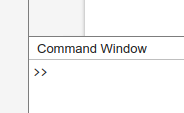

Si escribimos una operación en este panel, Matlab la ejecutará de inmediato. Por ejemplo, tras escribir "2 + 2" (sin las comillas), Matlab nos dirá el resultado:

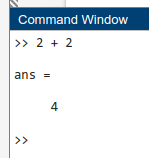    (Pruébelo usted también).

Observe como la respuesta es 4. En este modo interactivo, cuando ejecutamos una nueva operación, Matlab "se olvida" del resultado anterior. Matlab almacena el último resultado en la variable "ans", que podemos utilizar para el cálculo inmediatamente siguiente. Por ejemplo, si tras la orden anterior escribimos "ans + 4", obtendremos:

Como esta forma de trabajar es bastante precaria, ya que un error hará que se sobreescriba el resultado anterior con un resultado erróneo, lo habitual es trabajar dando nombre a los valores que nos interese conservar. Esto es, asignamos el resultado explícitamente a una variable.

Una asignación a una variable se hace con el operador "=". Las variables no necesitan ser declaradas como en Pascal, sino que se crean en el momento de asignárseles un valor. Si escribimos

Matlab nos responderá con 

Y "dos" almacenará su valor hasta que salgamos de Matlab o ejecutemos la instrucción "clear variables".

### Hacer operaciones sin mostrar el resultado

Ver el resultado de las operaciones en modo interactivo es conveniente para comprobar resultados sobre la marcha. A veces, sin embargo, nos interesa que no se imprima el resultado. Esto se consigue añadiendo un ";" al final de la instrucción:

Aunque parece que "no haya pasado nada", Matlab ha hecho el cálculo y lo ha almacenado en la variable "cuatro". Puede comprobarlo escribiendo el nombre de la variable, para que sea evaluada y se muestre su contenido:

O puede ver el valor de todas las variables existentes en el panel *"Workspace"*, normalmente situado en la parte inferior izquierda:

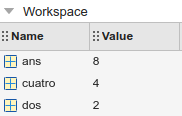

**Normalmente usaremos el modo interactivo para hacer cálculos rápidos y comprobar el valor de variables y, en general, para cálculos que no nos importa perder**. En cambio, cuando queramos conservar una serie de cálculos, lo haremos en un *Live Script*, como se explica a continuación. **En particular, la práctica 1 debe ser ejecutada y entregada como un *****Live Script.***

## Trabajar mediante *Live Scripts*

Un *Live Script* es como un cuaderno de notas, en el que almacenamos los cálculos de interés, pudiendo volver sobre nuestros pasos y corregirlos.

Este fichero que está viendo, Prac*0.mlx*, es un Live Script, aunque por el momento solo se ha utilizado para mostrar texto. Sin embargo, se pueden intercalar trozos de código:

raiz = sqrt(9)

Pulse con el ratón en la línea anterior (que lleva a su izquierda un "1" para indicar que es la primera línea de código) y pulse "Control+Enter" o el botón verde "Run" en la barra superior. En cualquiera de los dos casos,** Matlab ejecutará de arriba a abajo todos los bloques de código en el script**, mostrando de forma intercalada o a su derecha los resultados de aquellas instrucciones que no terminen en ";", como hemos visto.

La ventaja de los Live Scripts es que no se pierde el historial de lo que hayamos hecho. Además, como ve, se pueden intercalar descripciones.

He aquí otro ejemplo de código:

tres = 3

% Esto es un ejemplo de comentario en el código. 
% Matlab se salta las líneas que empiezan por '%' 

% Ahora sumo tres y tres:
tres + tres

✍ Ejecute el código anterior como se acaba de explicar y observe el resultado. Observe también que la nueva variable aparece a la izquierda en el panel "Workspace".

En determinados bloques de código,** los profesores les pedirán que completen o rellenen** lo que falta:

% COMPLETE ESTE CÓDIGO
% Asigne a la variable mostrada a continuación el valor apropiado:
cinco = x % <-- Corrija este valor (debería ser 5 en lugar de 'x')

## Observaciones sobre la edición del Live Script

MUY IMPORTANTE:

- Matlab le permite editar cualquier parte del Live Script, incluyendo todo el texto y código. **EDITE ÚNICAMENTE LOS FRAGMENTOS QUE LE PIDA EL ENUNCIADO**. De lo contrario puede destruir información o código relevante para el resto de la práctica.

- Si en un cuadro de código se produce un error, la ejecución se detiene. Por lo tanto, deberá ir corrigiendo todo código que se le pida antes de poder continuar (como es el caso del código en la línea 11).

A veces, para introducir el valor de variables, se encontrará cuadros de texto u otros controles:

% Introduzca su nombre a continuación:
Mi_nombre = ""

% Seleccione su edad en el deslizador:
Mi_edad = 99

Los resultados pueden usarse en bloques de código posteriores, puesto que se trata de variables normales:

disp(strcat("Ahora sé que ", Mi_nombre, " tiene ", string(Mi_edad), " años."))

## **Configuración personalizada de la práctica**

Normalmente, lo primero que deberán completar al inicio de una práctica será algo como lo siguiente:

% RELLENE los NIAs de los integrantes de la práctica. Deje el segundo a
% cero si la hace en solitario.
NIA_1 = 0; % <-- Completar con el NIA del primer miembro del equipo
NIA_2 = 0; % <-- Completar con el NIA del segundo miembro del equipo
p0.datos_iniciales(NIA_1, NIA_2); % no modificar esta línea

Este paso es fundamental para que se asocie el entregable a su identidad y para que se le proporcionen los datos correctos individualizados.

## **Entregar un Live Script como resultado de una práctica**

Los profesores pondrán a su disposición un script de partida (un fichero con extensión .mlx) que usted deberá completar y entregar. Para ello, siga los siguientes pasos cuando haya finalizado la práctica:

- **Guarde su trabajo** con el botón "Save" situado arriba a la izquierda, dentro de la pestaña "LIVE EDITOR": . Alternativamente puede pulsar en la flecha de debajo y utilizar "Save as..." para conservar el fichero con un nuevo nombre.

- **Si está trabajando con Matlab online**, en el listado de archivos que tiene a la izquierda, haga clic con el botón derecho sobre el Script que está editando (por ejemplo, Prac0.mlx en este caso) y **descárguelo a su ordenador** con la opción "⭳Download".

- Si, por el contrario, está trabajando con Matlab instalado en su ordenador, simplemente tome nota de la ubicación del archivo que está editando.

- **En el Moodle de la asignatura**, en la práctica correspondiente, haga uso de la opción para **entregar archivos**. Puede practicar con el el apartado al efecto dentro de la "Práctica 0" y este mismo Live Script.

∾ **FIN **∾